# Problem 2: Aerobraking

Student 1: Álvaro Reviriego Moreno 

Student 2: Enrique Sentana Gómez

Data of the problem:

clear all;
mu = 42828.4;                       % mu Mars [km^3/s^2] 
RM = 3389.9;                        % Radius of Mars [km]

a = 5940;                           % Semi-major axis [km]
e= 0.4;                             % Eccentricity 
Omega = deg2rad(194);               % RAAN 
i = deg2rad(56);                    % Inclination 
omega = deg2rad(258);               % Argument of periapsis 

theta_0 = deg2rad(230);             % True anomaly at t=0 
S = 10;                             % Shield area [m^2]
m = 3000;                           % Mass of the spacecraft [kg]


## Initial position and velocity vectors

The goal of this second problem related to aerobraking consist on analyzing the effect of the atmospheric drag on the evolution of the orbit of a determined body. In order to do the described task, the first step is to compute the initial state vector $X = [\vec{r},\vec{v}]$ from the given COEs. In order to do this, the function `coe2stat.m `is used. 

X_init = coe2stat([a,e,i,Omega,omega,theta_0],mu)       % Initial state vector 

X_init = 1.0e+03 *

    4.7283
   -1.8713
    4.3878
    0.0009
    0.0014
   -0.0017


## Ideal 2BP Cowell propagation and convergence study

This section is devoted to analyze the propagation returned from a numerical integrator for different values of $\delta t$. The values selected for the time-step are $\delta t = [300, 150, 75, 37.5] s$. The method used to calculate the propagation of the orbit 'Runge-Kutta $4^{th}$ order' (RK4) integrator. 

Runge-Kutta methods are a set of implicit and explicit iterative methods of numerical resolution of ordinary differential ecuations (ODE). If we define an initial value problem (IVP)

 $y' = f(x,t)$, with $y(x_0) = y_0$

The following RK4 steps is implemented by the following scheme


$$y_{i+1} = y_{i} + \frac{1}{6}h(k_{1} + 2k_{2}+2k_{3}+k_{4})$$


where $h $ is the time step and k are the intermediate coefficients, given by the following set of equations 


$$
k_{1} = f(x_{i},y_{i}) \\
k_{2} = f(x_{i}+ \frac{1}{2}h, y_{i}+ \frac{1}{2}hk_{1})\\
k_{3} = f(x_{i}+ \frac{1}{2}h, y_{i}+ \frac{1}{2}hk_{2}) \\
k_{4} = f(x_{i}+h, y_{i}+hk_{3})
$$


As we can see above, in order to implement the RK4 method, we must define clearly the set of ODEs that governs the orbit of the body. There are many ways to define the differential equations governing the propagation of the orbit, but in this task Cowell's formulation is used. Cowell's formulation consist on adding to the gravitational acceleration of the body (the one with no perturbation) the acceleration due to the atmospheric drag, which can be defined as 


$$\vec{a_{P}} = -\frac{1}{2\cdot B_{c}} \cdot  \rho\cdot v\cdot \vec{v} = -\frac{1}{2} \frac{C_{D}S}{m_{P}} \cdot \rho\cdot v\cdot \vec{v}$$


This acceleration due to the drag is calculated in the function `drag_acceleration.m`. We must also note that the density of the atmosphere ($\rho$) is calculated in the function `Mars_atmosphere.m`. In this function...(**Explicar mars atmosphere cuando este bien**) 

Once the perturbation acceleration is calculated, we can pose the Cowell's formulation of the 2-Body perturbed problem, implemented in the `Cowell.m `function


$$\frac{\mathrm{d^2} \vec{r}}{\mathrm{d} t^2} = - \frac{\mu}{r^3}\vec{r} + \vec{a_{P}}$$


The mentioned `Cowell.m `function is the one introduced in the RK4 integrator to propagate the orbit in time. Note that in the implemented function `RK4.m`, we define a flag as input. This flag is set to true if we want to compute the perurbed orbit, and set to false if we do not want to, leading to $\vec{a_{P}} = 0$. The goal of this section consist on analyzing the orbit with no perturbations, so the flag is set to false. 

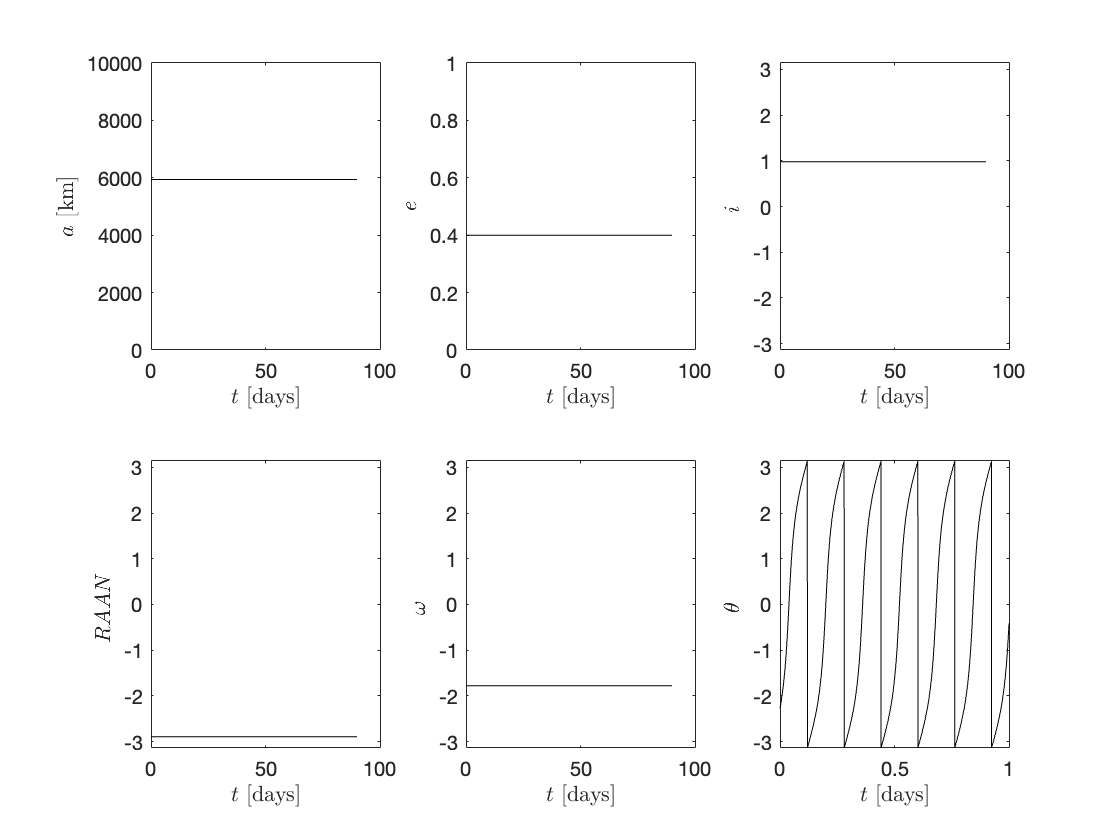

flag = false;
tf = 90*24*3600;

dt1 = 300;
t1 = 0:dt1:tf;
X1 = RK4(X_init,dt1,flag);

for j =1:length(X1)
    coe1(:,j) = stat2coe(X1(:,j),mu); 
end


figure(1)
plot_orbit(t1,coe1)

dt2 = 150; 
t2 = 0:dt2:tf;
X2 = RK4(X_init,dt2,flag);

for j =1:length(X2)
    coe2(:,j) = stat2coe(X2(:,j),mu); 
end

figure(2)
plot_orbit(t2,coe2)

dt3 = 75;
t3 = 0:dt3:tf; 
X3 = RK4(X_init,dt3,flag);

for j =1:length(X3)
    coe3(:,j) = stat2coe(X3(:,j),mu); 
end

figure(3)
plot_orbit(t3,coe3)

dt4 = 37.5;
t4 = 0:dt4:tf;
X4 = RK4(X_init,dt4,flag);

for j =1:length(X4)
    coe4(:,j) = stat2coe(X4(:,j),mu); 
end

figure(4)
plot_orbit(t4,coe4)

And you can add more code/text blocks as needed.

## Perturbed 2BP Cowell propagation

This section is devoted to analyze the propagation of the orbit under the effect of the perturbation due to drag acceleration. In this case, the formulation is the same as in the previous section, with the main difference that now $\vec{a_{P} \neq 0$, so the flag is set to true. Moreover, we must note that in this section the time step used is $\delta t_{4} = 37.5 s$.

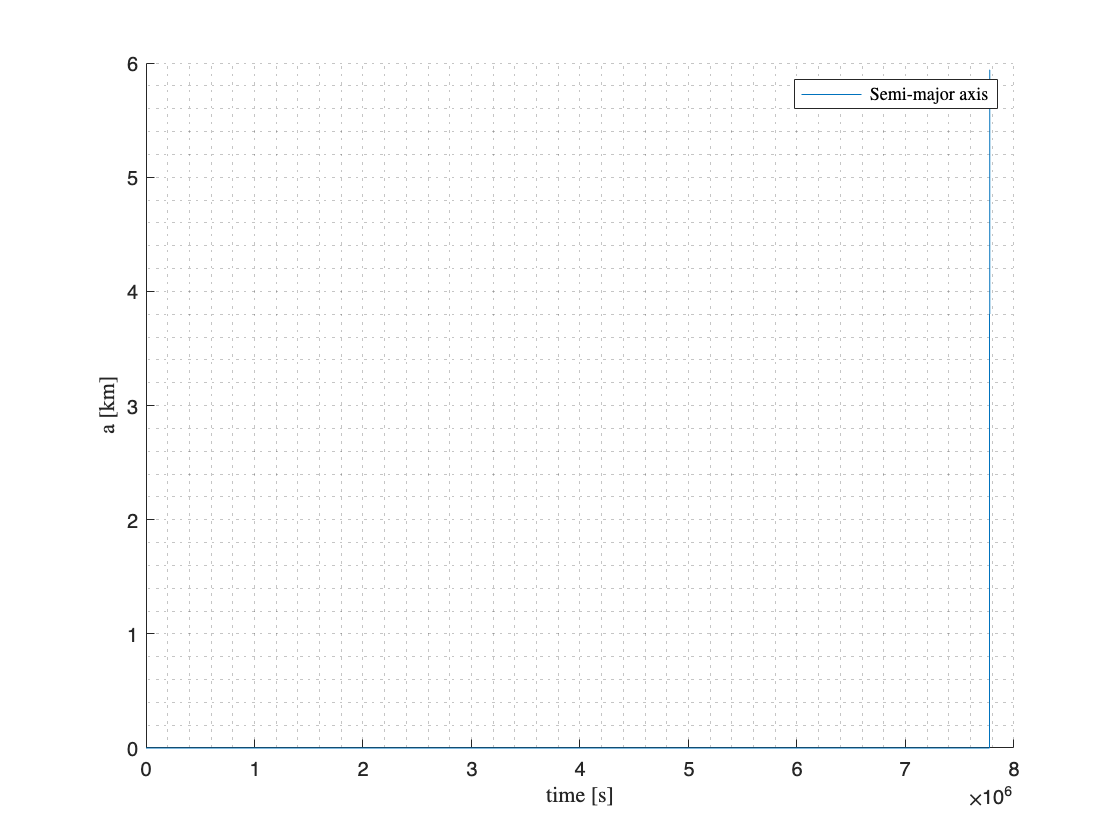

X4_2 = RK4(X_init,dt4,true);

for k=1:length(X4_2(1,:))
    if norm(X4_2(1:3,k))<50
        return
    end
    coe4_2(:,j) = stat2coe(X4_2(:,j),mu);
end


figure 
hold on
grid minor
plot(t4,coe4_2(1,:)/1000)
legend('Semi-major axis',Interpreter='latex')
xlabel('time [s]',Interpreter='latex')
ylabel('a [km]',Interpreter='latex')
hold off

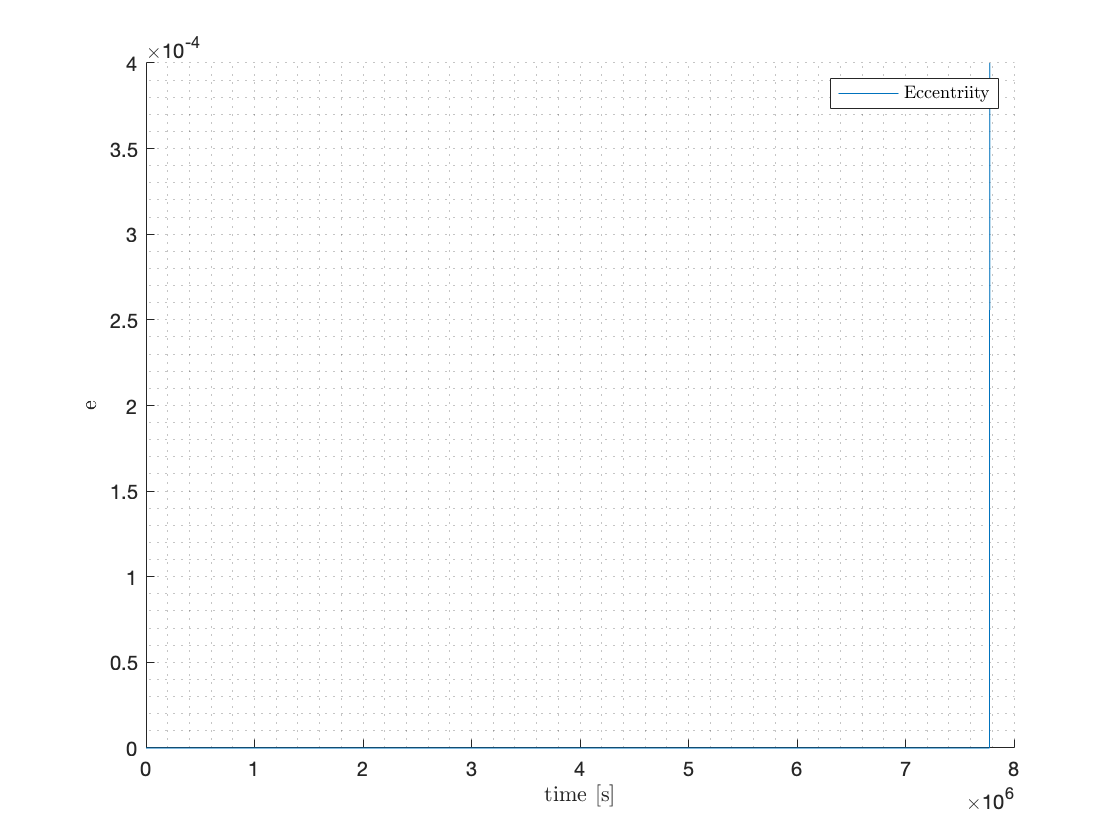


figure 
hold on
grid minor
plot(t4,coe4_2(2,:)/1000)
legend('Eccentriity',Interpreter='latex')
ylabel('e',Interpreter='latex')
xlabel('time [s]',Interpreter='latex')
hold off

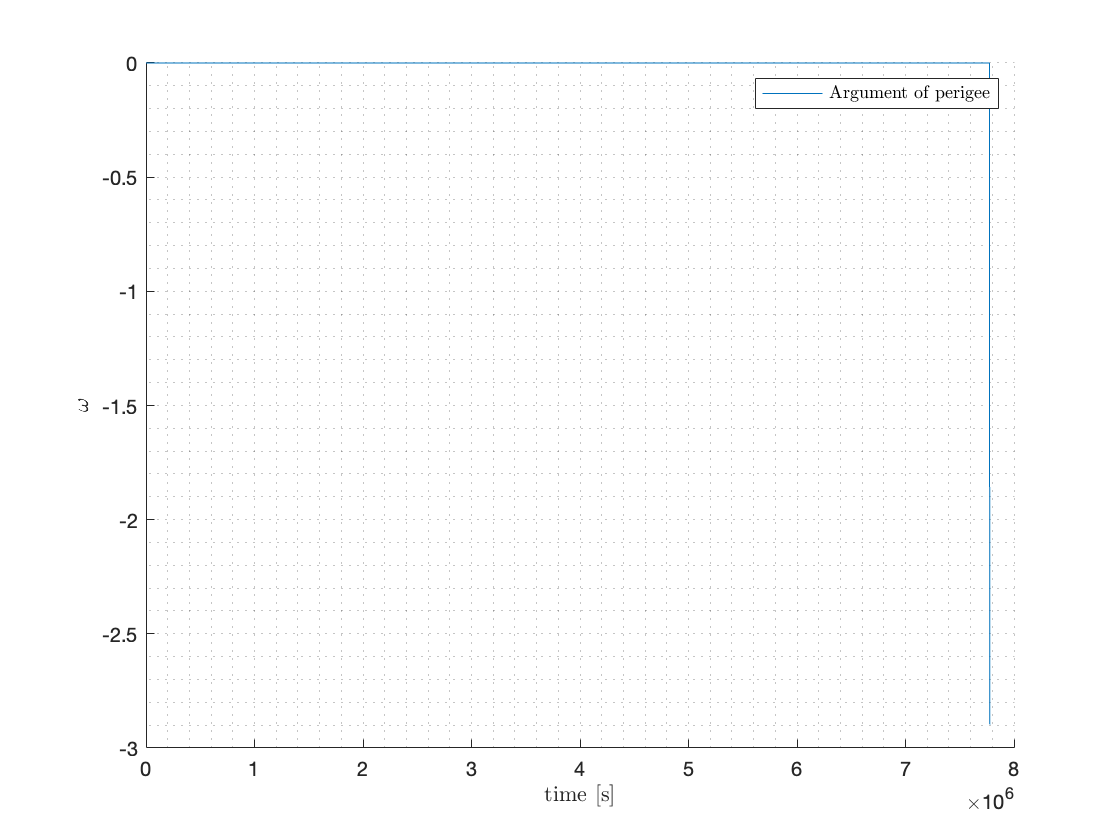


figure 
hold on
grid minor
plot(t4,coe4_2(4,:))
legend('Argument of perigee',Interpreter='latex')
ylabel('$\omega$',Interpreter='latex')
xlabel('time [s]',Interpreter='latex')
hold off

## Time to reentry

% ...

## Discussion

(Complete your report with any comments you may like to add)